# **Embedded Coder Support Package for Texas Instruments AM13x**

[Back to main page](matlab:open('../chapter_1_introduction/introduction_am13x.mlx'))

Peripheral Blocks are not available in this release. They will be coming in the following releases. Only Hardware Interrup block is available to create interrupt handlers

### Hardware Interrupt block:

#### Block Mask:

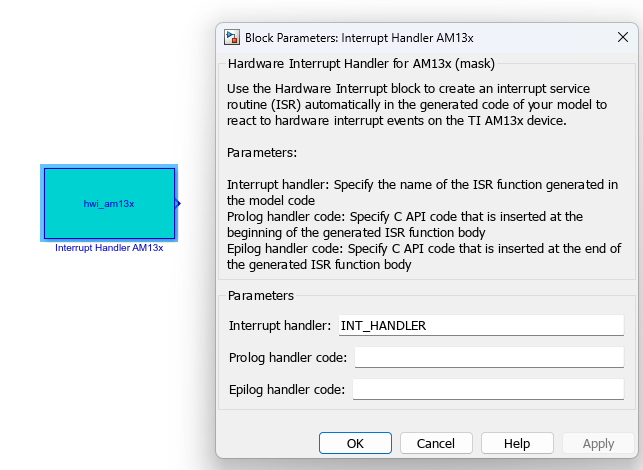

#### Library view:

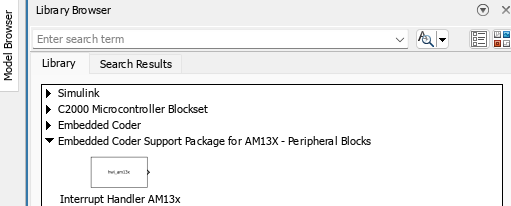

**Parameters:**

- **Interrupt handler name**: The name of the ISR function generated in the model code. This must match exactly the interrupt handler symbol expected by the AM13x VIM interrupt vector table. The handler name is either:

- Defined in the SysConfig tool (.syscfg file), where the peripheral interrupt is registered and routed to this symbol.

- A static handler name from the AM13x SDK startup/vector table files.

For example: MTR1_FOC_INT1_Handler

2. **Prolog handler code:** C code inserted at the beginning of the ISR, before any Simulink-generated code executes. Typically used for:

- Disable interrupts/Read and snapshot hardware status registers early in the ISR.

- Call any AM13x SDK APIs calls that must run before the function-call subsystem is invoked. 

**3. Epilog handler code: **C code inserted at the **end** of the ISR, after all Simulink-generated code has executed. Typically used for:

- Clear peripheral interrupt flags to allow the next interrupt to be recognized. 

- Re-enable interrupts that were disabled in the prolog.

- Emit any acknowledgment or cleanup calls required by the AM13x peripheral driver.

`Example for prolog or epilog code:`

DL_ADC_clearInterruptStatus(ADC_0_INST, DL_ADC_INT_NUMBER1)

`Above code clears ADC interrupt status.`

[Back to main page](matlab:open('../chapter_1_introduction/introduction_am13x.mlx'))